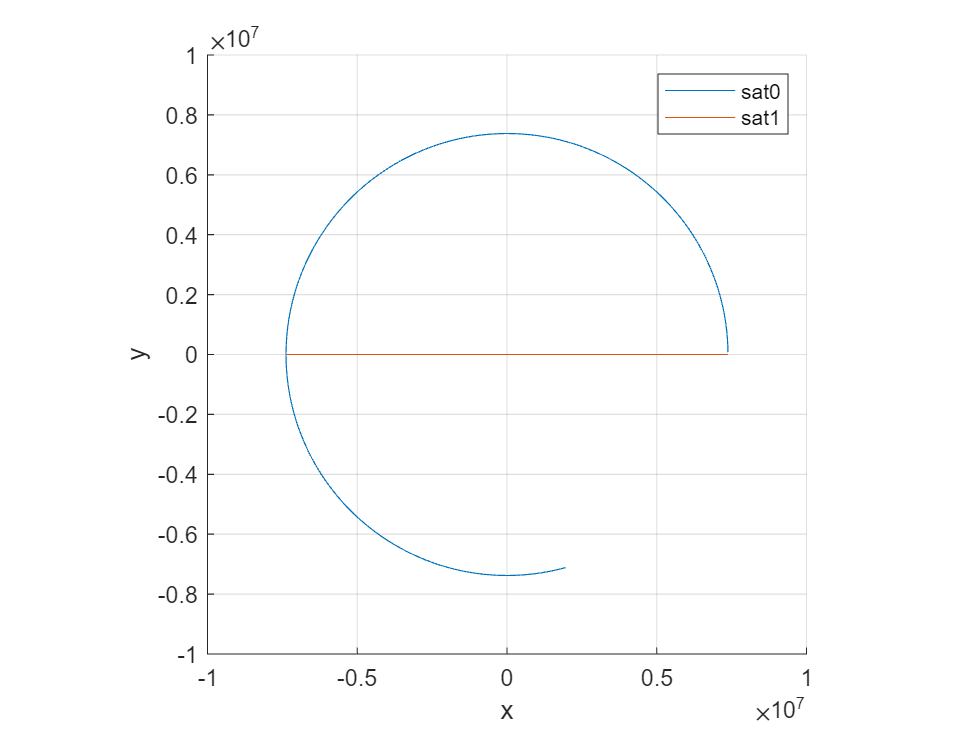

opts = delimitedTextImportOptions("NumVariables", 3);

directory = pwd;  % Specify the directory path
files = dir(fullfile(directory, 'output*'));  % Get a list of files matching the pattern

num_sats = numel(files);  % Count the number of files

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["x", "y", "z"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data and plot
figure(1)
hold on
xlim([-10000e3,10000e3])
ylim([-10000e3,10000e3])
zlim([-10000e3,10000e3])
xlabel("x"),ylabel("y"),zlabel("z")
axis("equal")
grid on
leg = cell(1,num_sats);
for i = 0:num_sats-1
    fn = "output" + num2str(i);
    filename = fn + ".txt";
    output.(fn) = readtable(filename,opts);
    satname = "sat" + num2str(i);
    x.(satname) = output.(fn).x;
    y.(satname) = output.(fn).y;
    z.(satname) = output.(fn).z;

    plot3(x.(satname),y.(satname),z.(satname))
    leg{i+1} = satname;
end
clear opts output
legend(leg)